clc;clear;

## Aufgabe1

A = [3 0 0 0;
     0 3 0 0;
     0 0 3 0;
     0 0 0 3]; %% Matrix A define
v = [1;2;3;4]; %% column vector v define
a = v' * v

a =     30

B = v * v'

B =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16


C = A * B

C =      3     6     9    12
     6    12    18    24
     9    18    27    36
    12    24    36    48


lambda_C = eig(C)

lambda_C =   -0.000000000000002
   0.000000000000000
   0.000000000000004
  90.000000000000000


## Aufgabe 2

A = rand(1,1000); %% the method to create random number: rand, randi 
if A(1) >= 0.5
    fprintf('a1 >= 0.5 \n');
else
    fprintf('a1 < 0.5 \n');
end

a1 < 0.5 



n05 = 0;
for a = 1:1000
    if A(a) >= 0.5
        n05 = n05 +1;
    end
    a = a + 1;
end
fprintf("n05 = %d \n", n05);

n05 = 519 



i = 1;
while (i <= 1000)
    if A(i) >= 0.499 && A(i) <= 0.501
        fprintf("index is %d, value is %f \n",i,A(i));
        break;
    else
        i = i + 1;
    end
    if i==1000
        fprintf("Kein Element 0.499 <= a_i <= 0.501 \n");
    end
end

index is 121, value is 0.500940 


## Aufgabe 3

### 3.1 2D-Plot

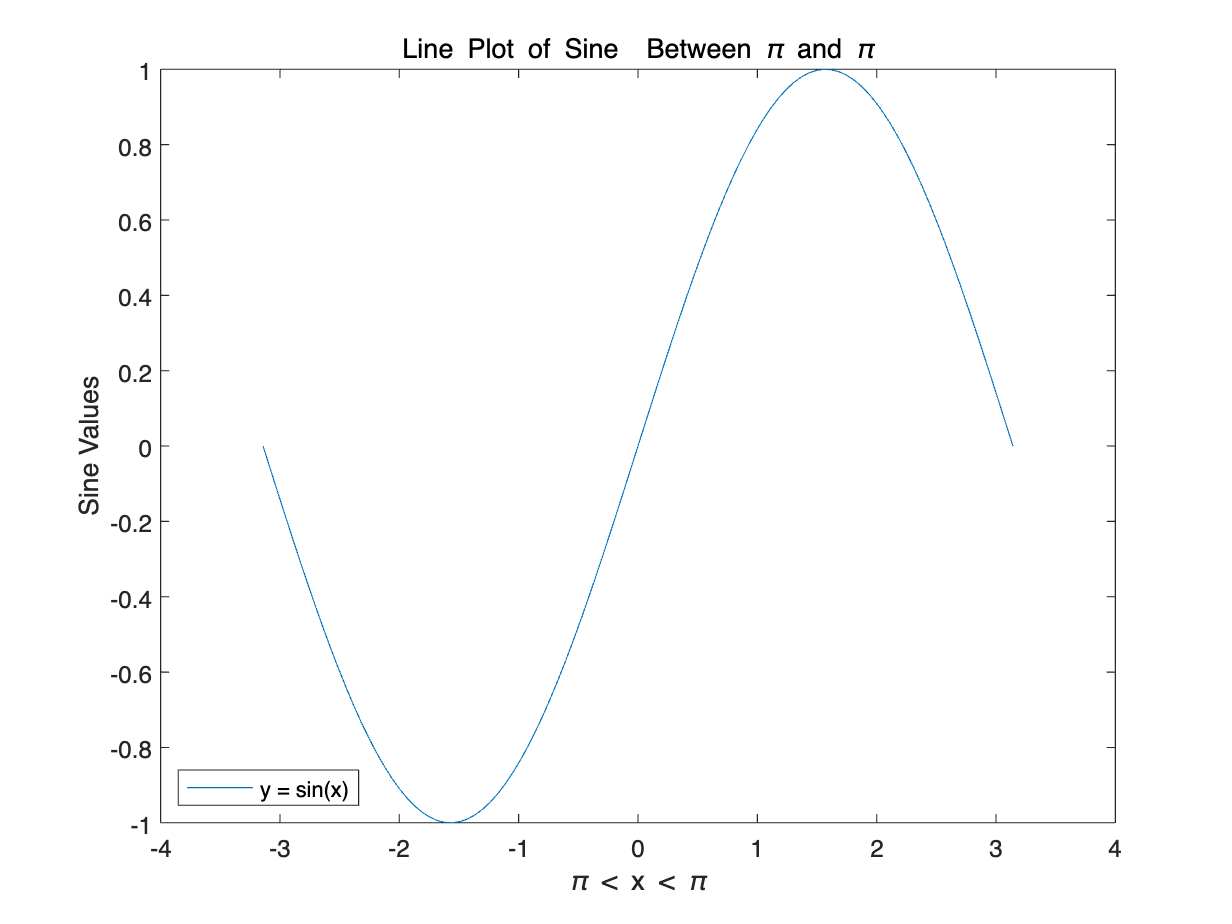

%3.1
% syms x
% f = @(x)sin(x);
% x = linspace(-pi, pi, 100);
% plot(x,f(x))
x = linspace(-pi,pi,100);
y = sin(x);
figure
plot(x,y)
title('Line Plot of Sine  Between \pi and \pi')
xlabel('\pi < x < \pi') 
ylabel('Sine Values') 
legend({'y = sin(x)'},'Location','southwest')

### 3.2 3D-plot

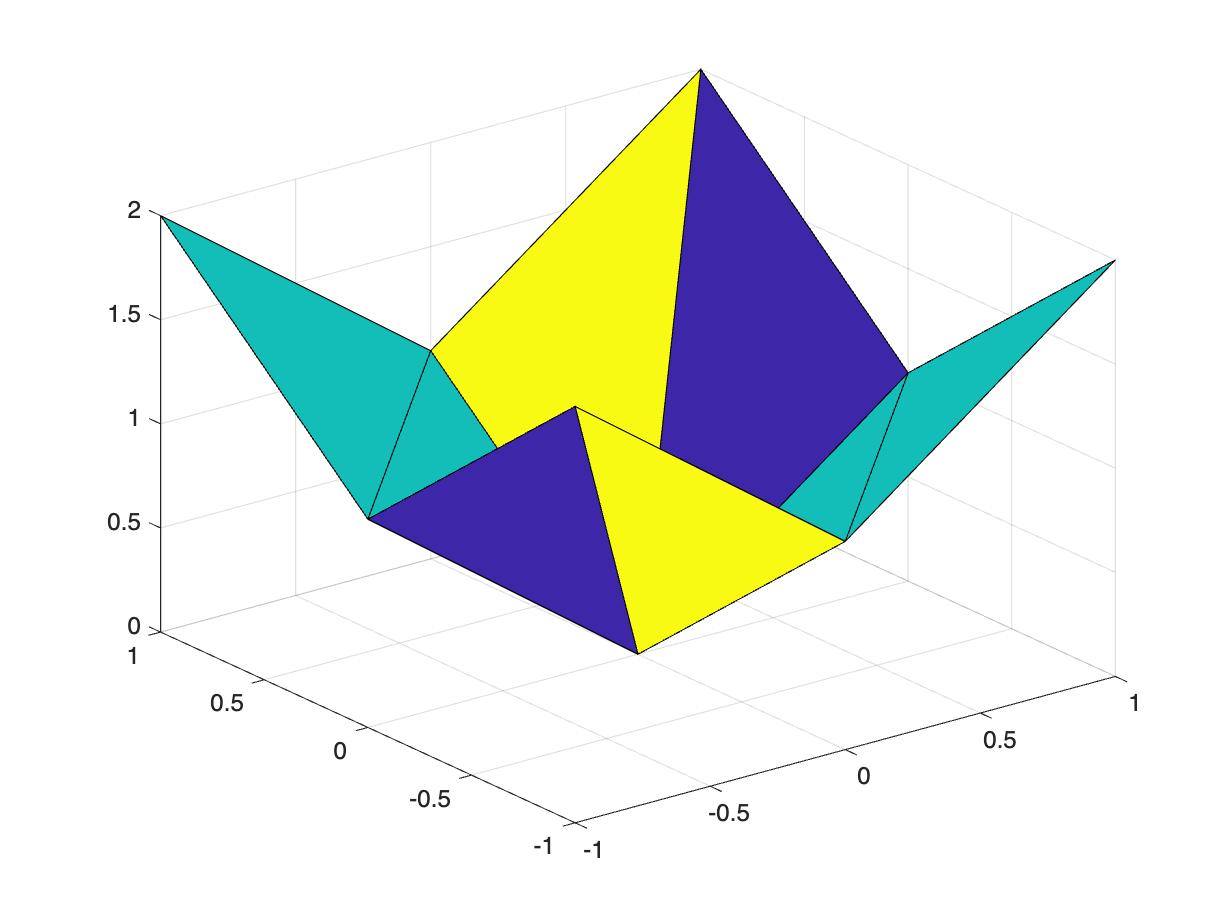

nodes = [-1, -1; 0, -1; 1, -1; -1, 0; 0, 0; 1, 0; -1, 1; 0, 1; 1, 1];
elements = [
    1, 2, 5, 4; 
    2, 3, 6, 5; 
    4, 5, 8, 7; 
    5, 6, 9, 8];
sol = [2; 1; 2; 1; 0; 1; 2; 1; 2];
fkt0(nodes,elements,sol)
grid on

## Fakultaet

x = fakultaet(3)

x =      6

function a = fakultaet(n)
 a = factorial(n);
end

## Modultest

% Define a tolerance
tol = 1e-12;
% test function : facultaet
modultest(fakultaet(0),1)

test passed


modultest(fakultaet(5),120)

test passed


function fkt0(nodes,elements,sol)
x = nodes(:,1);
y = nodes(:,2);
T = [elements(:,1:3);elements(:,3:4),elements(:,1)];
trisurf(T, x, y, sol);
end